## 13E054MAS Metode analize elektrofizioloških signala

**Seminarski rad II**

**student:** Aleksandra Ljubenović 2020/0117

U ovom zadatku bilo je potrebno razdvojiti višekanalni elektrohisterogram (EHG) sa 16 kanala na nezavisne komponente primenom ICA (*engl. Independent Component Analysis*) metode po izboru i komentarisati sadržaj izvornih komponenti. Za izvornu komponentu koja odgovara elektrokardiogramu (EKG) majke bilo je potrebno realizovati metodu za detekciju R pikova, odrediti RR intervale i komentarisati stohastičnost i periodičnost srčanog ritma.

**Učitavanje signala**

Signali koji su korišćeni u ovom zadatku deo su *PhysioNet* baze podataka *Icelandic 16-electrode Electrohysterogram Database* ([https://physionet.org/content/ehgdb/1.0.0/](https://physionet.org/content/ehgdb/1.0.0/)). Za analizu su odabrani signali trudnice čiji je ID *ice024*, koji predstavljaju elektrohisterograme snimane tokom porođaja (beba je rođena 3 sata i 7 minuta nakon početka snimanja) u trajanju od 25 minuta i 20 sekundi. Podaci koji su korišćeni u zadatku učitani su iz tri različite datoteke: 

- "*ice024_l_1of1.hea*"  - zaglavlje u WFDB (*engl. waveform-database*) formatu koje sadrži informacije o hardveru koji je korišćen za akviziciju signala kao i generalne informacije o trudnici i porođaju;

-  "*ice024_l_1of1.dat*" - binarna datoteka koja sadrži elektrohisterograme dobijene sa 16 monopolarnih Ag/AgCl elektroda;

-  "*ice024_l_1of1m_ann.mat*" - datoteka sa anotacijama koja sadrži vrste i vremenske odbirke događaja za koje je manuelno zabeleženo da su se dogodili tokom akvizicije signala.

Pozicije svih 16 elektroda na stomaku trudnice tokom snimanja prikaze su na sledećim slikama.

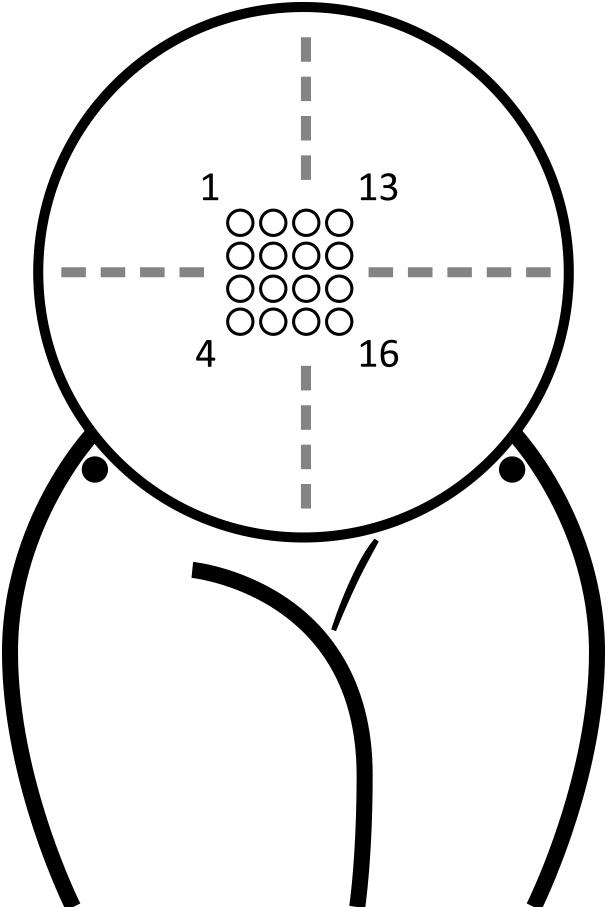           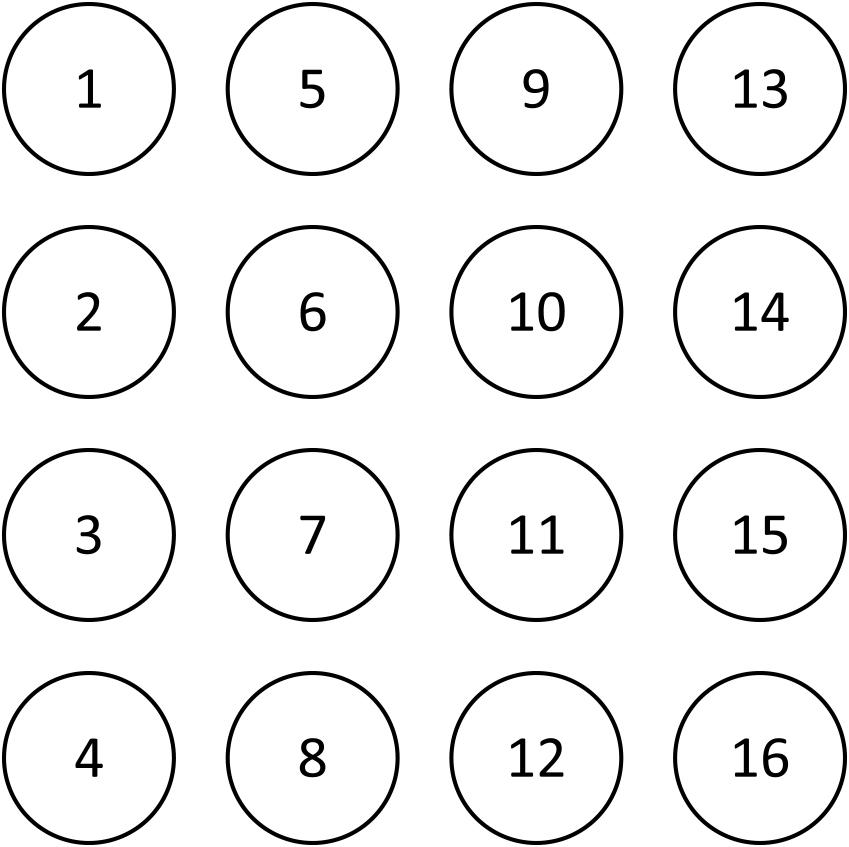

Dodatno, za ovo snimanje dostupan je i skenirani signal sa tokograma u *.jpg* formatu na kome je ručno dodata vremenska osa (svaki mali kvadratić predstavlja 30 sekundi). Izgled ovog signala prikazan je na sledećoj slici:

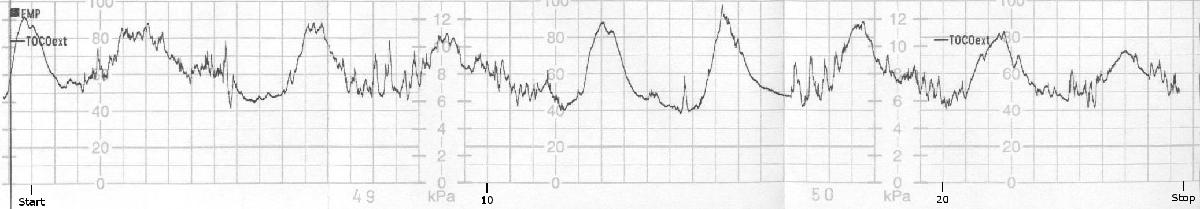

U opisu baze podataka naznačeno je da dostupne anotacije predstavljaju komplement signalu sa tokograma tj. da neke kontrakcije koje su naznačene u anotacijama nisu očigledne na tokografu kao i da neke kontrakcije koje su očigledne na tokografu nisu prisutne u anotacijama.

clear; close all; clc

% Icelandic 16-electrode Electrohysterogram Database
% https://physionet.org/content/ehgdb/1.0.0/
% WFDB format

% Subject ID: ice024
% Record type: labour 1
% Duration of recording (hh:mm:ss): 00:25:20

HEADERFILE = 'data/ice024_l_1of1.hea';
DATAFILE = 'data/ice024_l_1of1.dat';
ANNFILE = 'data/ice024_l_1of1m_ann.mat';

[EHG_data, n_sig, fs, n_samp, ADC_gain, ch_numbers] = load_data(HEADERFILE, DATAFILE);

**Vizuelizacija signala**

Nakon učitavanja navedenih datoteka koje je izvršeno na osnovu pravila za čuvanje signala u WFDB formatu, izvršeno je skaliranje amplitude sirovih elektrohisterograma pojačanjem A/D kartice koje iznosi 131.0680, kako bi se dobili EHG signali čija je amplituda u milivoltima. Frekvencija odabiranja ovih signala iznosi 200 Hz.

Na sledećem grafiku prikazano je prvih 10 s i poslednjih 10 s sirovog EHG signala sa prvog kanala. Posmatranjem navedenih grafika može se primetiti da na početku i na kraju akvizicije na sirovom signalu postoje gličevi, te je sa signala sa svih kanala pre dalje analize odsečeno prvih 2.5 s i poslednjih 5 s, kako bi se obezbedilo da ni na jednom kanalu nema ovakvih gličeva.

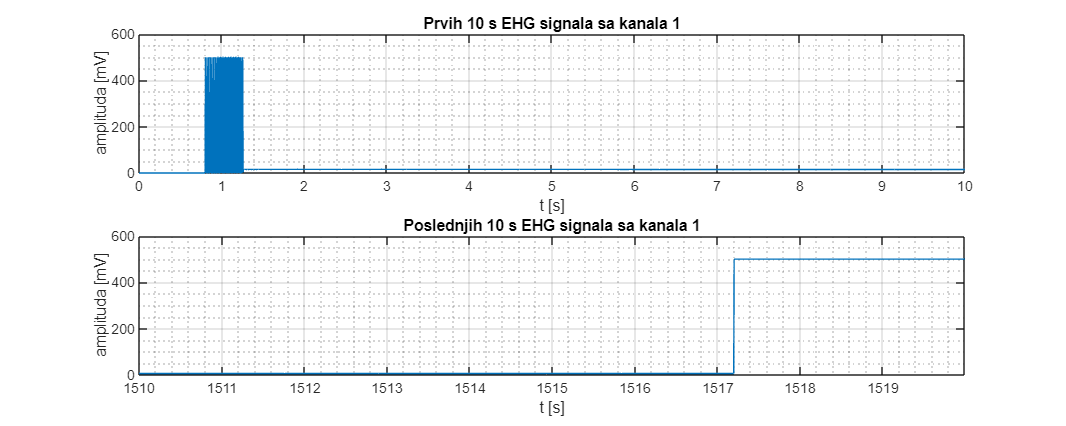

% Skaliranje amplitude signala na osnovu pojačanja A/D kartice
EHG_data = EHG_data./ADC_gain;

% Definisanje vremenske ose
t = (0:1/fs:(n_samp-1)/fs)';

% Izbor kanala za prikaz signala
ch_ind = 1;
ch_num = num2str(ch_numbers(ch_ind));

% Prikaz prvih i poslednjih 10 s signala sa jednog kanala
figure(position = [50 100 1000 400])
    subplot(2,1,1)
    plot(t,EHG_data(:,ch_ind))
    xlabel('t [s]'); ylabel('amplituda [mV]')
    title("Prvih 10 s EHG signala sa kanala " + ch_num)
    grid on; grid minor
    xlim([0 10])

    subplot(2,1,2)
    plot(t,EHG_data(:,ch_ind))
    xlabel('t [s]'); ylabel('amplituda [mV]')
    title("Poslednjih 10 s EHG signala sa kanala " + ch_num)
    grid on; grid minor
    xlim([t(end)-10 t(end)])

U nastavku je prikazan vremenski oblik signala sa prvog kanala nakon odsecanja prvih 2.5 s i poslednjih 5 s, kao i njegova amplitudska frekvencijska karakteristika (AFK). Posmatranjem amplitudske frekvencijske karakteristike može se uočiti da signal ima veoma veliku DC komponentu koja je reda veličine 1e6, kao i da je na signalu prisutan šum napajanja na 50 Hz.

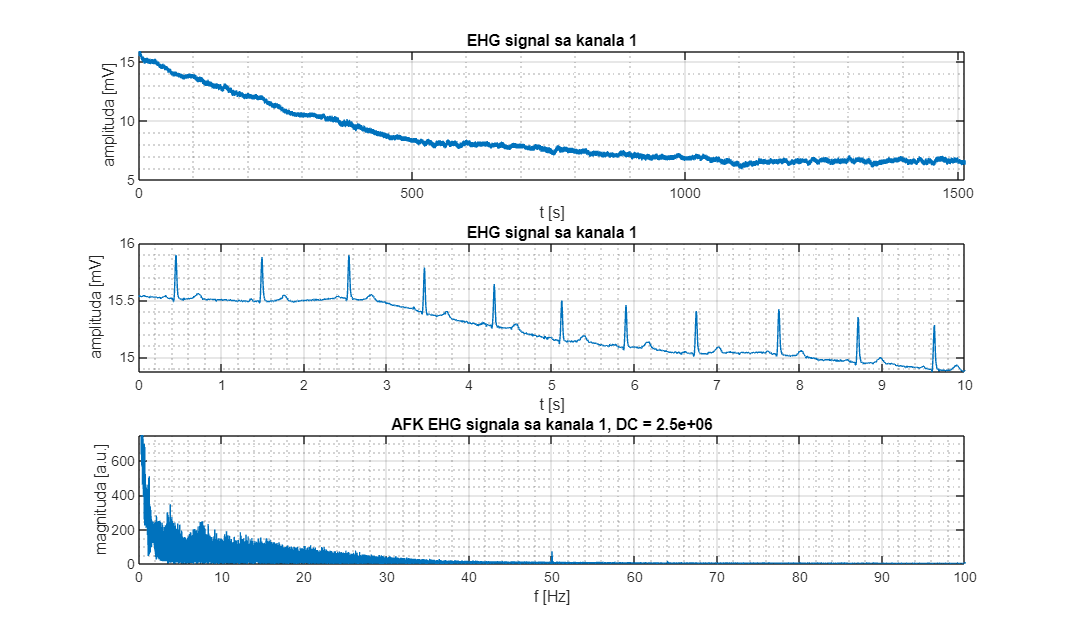

%% Uklanjanje prvih 2.5 s signala i poslednjih 5 s signala sa svakog kanala

ind_start = 2.5*fs;
ind_end = (t(end)-5)*fs;
EHG_data = EHG_data(ind_start:ind_end,:);

% Definisanje nove vremenske i frekvencijske ose
N = size(EHG_data,1);
t = 0:1/fs:(N-1)/fs;
f =  (fs/N)*((-N/2+1):(N/2));

% Prikaz EHG signala sa jednog kanala nakon odsecanja
data = EHG_data(:,ch_ind);
data_fft = fft(data);
DC = data_fft(1);
data_fft = fftshift(data_fft);

figure(position = [50,100,1000,600])
    subplot(3,1,1)
    plot(t,data)
    xlabel('t [s]'); ylabel('amplituda [mV]')
    title("EHG signal sa kanala " + num2str(ch_numbers(ch_ind)))
    grid on; grid minor
    xlim([0 t(end)])

    subplot(3,1,2)
    plot(t,data)
    xlabel('t [s]'); ylabel('amplituda [mV]')
    title("EHG signal sa kanala " + num2str(ch_numbers(ch_ind)))
    grid on; grid minor
    xlim([0 10])

    subplot(3,1,3)
    plot(f,abs(data_fft))
    xlabel('f [Hz]'); ylabel('magnituda [a.u.]')
    title("AFK EHG signala sa kanala "+num2str(ch_numbers(ch_ind))+", DC = "+num2str(DC,'%.1e'))
    grid on; grid minor
    ylim([0 7.5e2])
    xlim([0 fs/2])

Posmatranjem vremenskog oblika EHG signala lako se može zaključiti i da on sadrži artefakt koji odgovara EKG signalu majke (EHG signal fetusa nije ovako očigledan na sirovom signalu). Najveći deo energije EKG signala majke pripada opsegu frekvencija od 6 Hz do 30 Hz i ovo je činjenica koja će biti korišćena u toku dalje analize signala.

**Predobrada signala**

Pre primene ICA algoritma, sirov EHG signal je filtriran *highpass* filtrom kako bi se sa signala uklonila DC komponenta i *notch* filtrom kako bi se sa signala uklonio šum napajanja.

I u slučaju *highpass* filtriranja i u slučaju *notch* filtriranja orišćen je *Butterworth-*ov filtar 5. reda kako bi se obezbedio dovoljno strm prelaz između nepropusnog i propusnog opsega, a pri tome izbeglo talasanje i u nepropusnom i u propusnom opsegu.

Prilikom odabira učestanosti odsecanja *highpass* filtra potrebno je biti posebno pažljiv, jer posmatrani signal sadrži komponente od interesa na niskim učestanostima bliskim DC komponenti. Naime, čistom EHG signalu koji predstavlja mišićnu aktivnost materice odgovara frekvencijski opseg od 0.1 Hz do 3 Hz, pri čemu se najveća energija ovog signala nalazi u opsegu 0.1-1.5 Hz. U ovom opsegu frekvencija nalazi se i deo spektra koji odgovara respiraciji majke (oko 0.2 Hz), što onemogućava da se šum disanja ukloni iz EHG signala jednostavnim filtriranjem u frekvencijskom domenu. Dodatno, u opsegu učestanosti 0.1-1.5 Hz očekuje se prisustvo i komponenti koje odgovaraju srčanoj frekvenciji majke (oko 1.2 Hz) i respiraciji fetusa (oko 1 Hz).

Kako se prilikom* highpass* filtriranja ne bi uklonio deo spektra koji odgovara sporopromenljivom EHG signalu, odabrano je da frekvencija odsecanja *highpass *filtra bude 0.1 Hz. Uveličana amplitudska prenosna karakteristika korišćenog filtra prikazana je na sledećem grafiku.

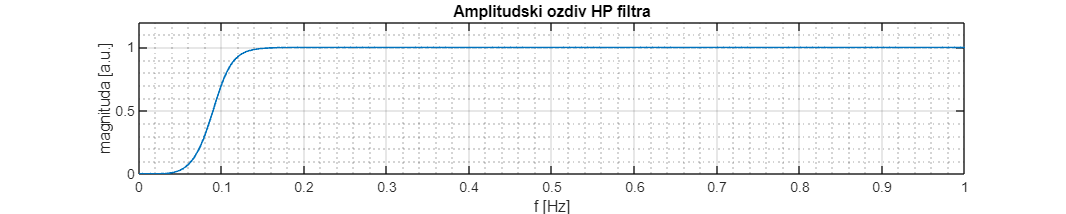

% Uklanjanje DC komponente
order = 5;
cutoff = 0.1;   % Hz

EHG_data_filt = highpass_filter(EHG_data,fs,cutoff,order);

*Notch* filtar implementiran je kao *Butterworth*-ov *bandstop *filtar čije su frekvencije odsecanja 49.5 Hz i 50.5 Hz, čime je obezbeđeno da se filtrira uzak opseg frekvencija oko šuma napajanja. Amplitudski odziv korišćenog filtra prikazan je na sledećem grafiku.

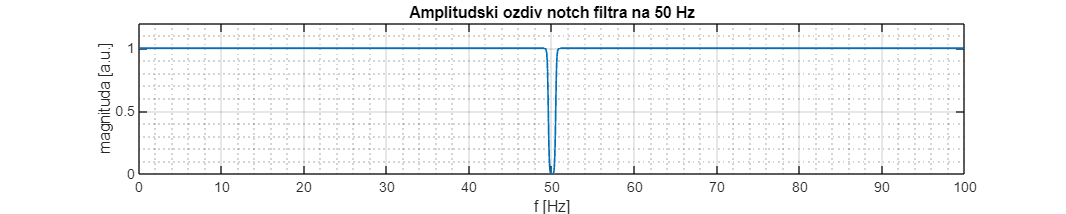

% Uklanjanje šuma napajanja na 50 Hz
order = 5;
EHG_data_filt = notch_filter(EHG_data_filt,fs,order);

I u slučaju *highpass* i *notch* filtriranja, obezbeđeno je* zero-phase* filtriranje (filtriranje koje minimizuje distorziju faze signala) upotrebom ugrađene *filtfilt()* funkcije. Vremenski i frekvencijski oblik signala sa prvog kanala nakon filtriranja prikazan je na sledećim graficima.

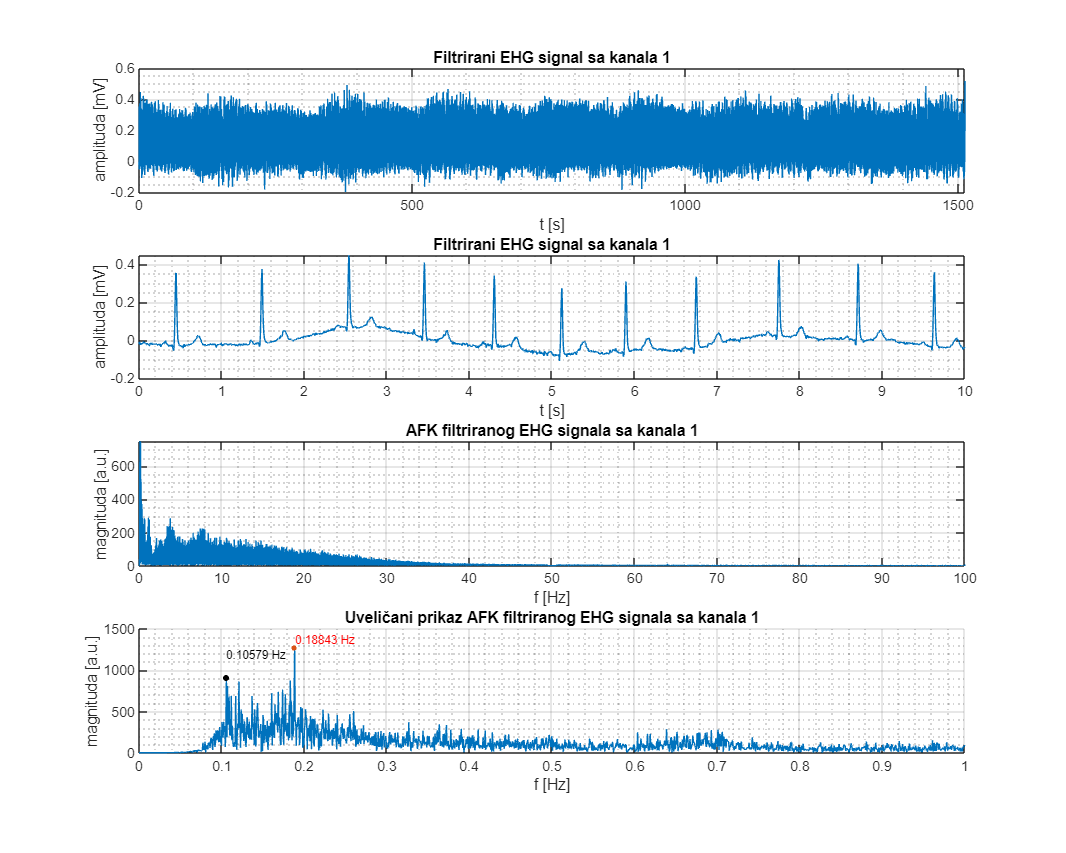

% Prikaz signala nakon filtriranja
data_filt = EHG_data_filt(:,ch_ind);
data_filt_fft = fftshift(fft(data_filt));

figure(position = [50,100,1000,800])
    subplot(4,1,1)
    plot(t,data_filt)
    xlabel('t [s]'); ylabel('amplituda [mV]')
    title("Filtrirani EHG signal sa kanala " + num2str(ch_numbers(ch_ind)))
    grid on; grid minor
    xlim([0 t(end)])

    subplot(4,1,2)
    plot(t,data_filt)
    xlabel('t [s]'); ylabel('amplituda [mV]')
    title("Filtrirani EHG signal sa kanala " + num2str(ch_numbers(ch_ind)))
    grid on; grid minor
    xlim([0 10])

    subplot(4,1,3)
    plot(f,abs(data_filt_fft))
    xlabel('f [Hz]'); ylabel('magnituda [a.u.]')
    title("AFK filtriranog EHG signala sa kanala " + num2str(ch_numbers(ch_ind)))
    grid on; grid minor
    ylim([0 7.5e2])
    xlim([0 fs/2])

    data_filt_fft = data_filt_fft(length(f)/2:end);
    f_tmp = f(length(f)/2:end);
    [peaks, locs] = findpeaks(abs(data_filt_fft));
    [peaks,ind] = sort(peaks,'descend');
    locs = locs(ind);

    peak = peaks(1); peak2 = peaks(2);
    loc = locs(1); loc2 = locs(2);

    subplot(4,1,4)
    hold all
    plot(f_tmp,abs(data_filt_fft))
    scatter(f_tmp(loc),peak,'filled','sizeData',10)
    scatter(f_tmp(loc2),peak2,'filled','sizeData',10,'MarkerEdgeColor','black','MarkerFaceColor','black')
    text(f_tmp(loc),peak,num2str(f_tmp(loc))+" Hz",'Color','red','FontSize',7,...
     'VerticalAlignment','bottom','HorizontalAlignment','left');
    text(f_tmp(loc2),peak,num2str(f_tmp(loc2))+" Hz",'Color','black','FontSize',7,...
     'VerticalAlignment','top','HorizontalAlignment','left');
    xlabel('f [Hz]'); ylabel('magnituda [a.u.]')
    title("Uveličani prikaz AFK filtriranog EHG signala sa kanala " + num2str(ch_numbers(ch_ind)))
    grid on; grid minor
    xlim([0 1])

Poslednji grafik koji je prikazan predstavlja uveličanu amplitudsku frekvencijsku karakteristiku u opsegu učestanosti 0-1 Hz. Može se uočiti da su frekvencije oko 0.1 Hz, iako nešto oslabljene, očuvane nakon filtriranja. Dodatno, maksimum AFK nalazi se na frekvenciji 0.1884 Hz (tačka označena crvenom bojom na grafiku) i za ovaj pik se može pretpostaviti da predstavlja učestanost disanja majke.

**BSS-CCA** *(engl. Blind Source Separation by Canonical Correlation Analysis)*

ICA metoda koja je odabrana za razdvajanje šesnaestokanalnog EHG signala na nezavisne komponente jeste kanonička korelaciona analiza (*engl. Canonical Correlation Analysis* - CCA) koja je primenjena kao tehnika za izdvajanje izvornih komponenti iz miksovanog signala bez ikakvog predznanja o izvornim komponentama (*engl. Blind Source Separation* - BSS).

Izvorne komponete koje su dobijene primenom CCA algoritma na filtrirani 16-kanalni EHG signal prikazane su u nastavku prema opadajućoj vrednosti njihove kanoničke korelacije (*engl. Canonical Correlation* - CC), zajedno sa svojim amplitudskim frekvencijskim karakteristikama.

Prva izdvojena komponenta predstavlja EKG signal majke koji je modulisan sporopromenljivom komponentom koja verovatno odgovara kontrakcijama materice i respiraciji majke i ova komponenta će kasnije biti korišćena za detekciju R pikova i analizu srčanog ritma majke.

I druga i treća izvorna komponenta takođe sadrže artefakt koji potiče od EKG signala majke (sadrže spektralne komponente u frekvencijskom opsegu od 6 do 30 Hz), ali pored toga sadrže i veliki deo energije u opsegu nižih frekvencija koji odgovara sporopromenljivom EHG signalu majke. Treća izvorna komponenta biće korišćena za izdvajanje signala koji odgovara kontrakcijama materice.

Ostale izvorne komponente (od 4. do 16.) takođe sadrže veliku energiju u opsegu niskih frekvencija, ali su veoma zašumljenje i čistom vizuelnom inspekcijom nije uspešno utvrđeno njihovo poreklo.

Srčanu aktivnost fetusa (fEKG), njegovu respiraciju i pokrete, kao i pokrete majke i aktivnost abdominalnih mišića nije bilo moguće vizuelno prepoznati ni na jednoj od ovako izdvojenih nezavisnih komponenti. 

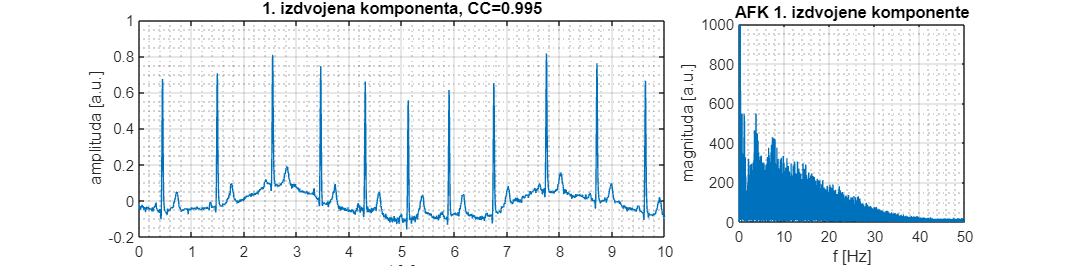

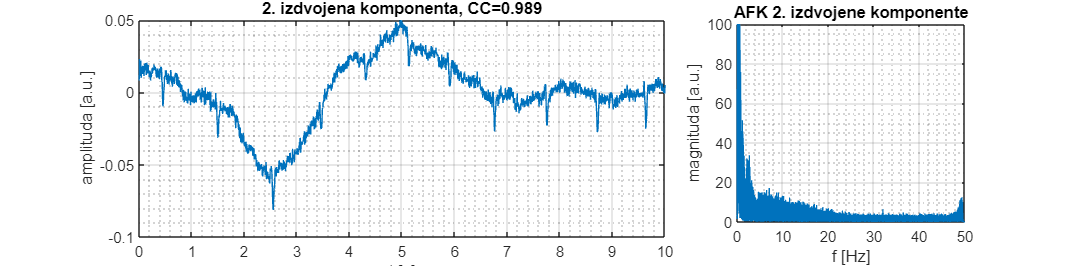

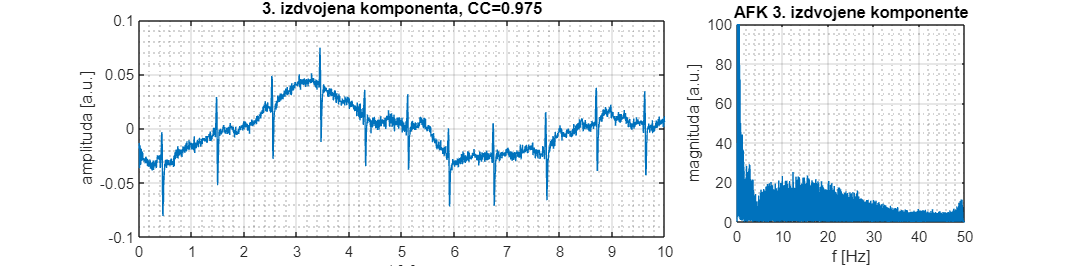

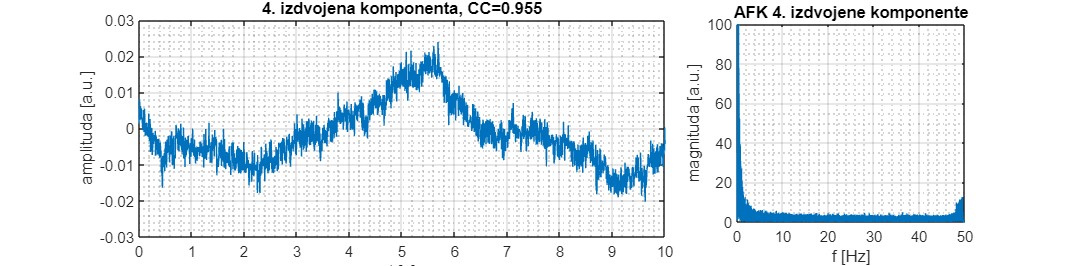

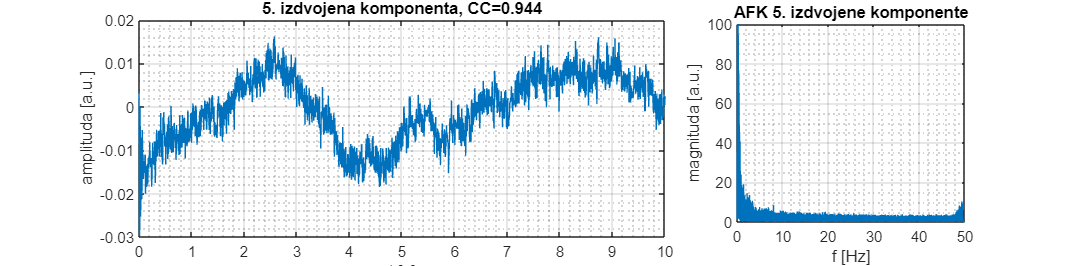

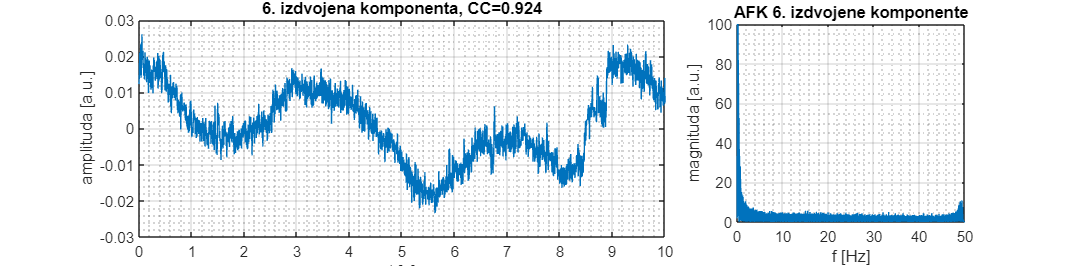

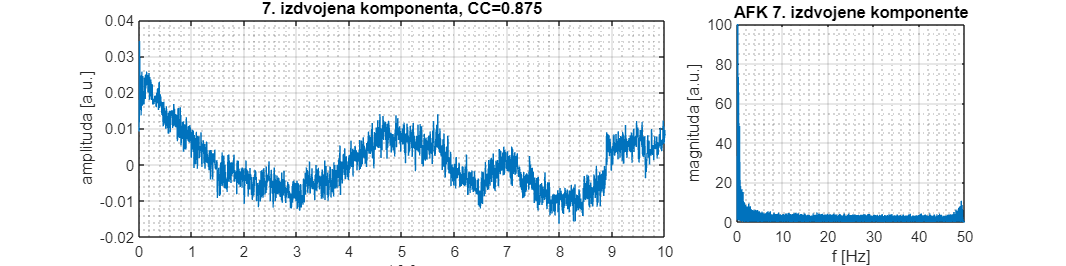

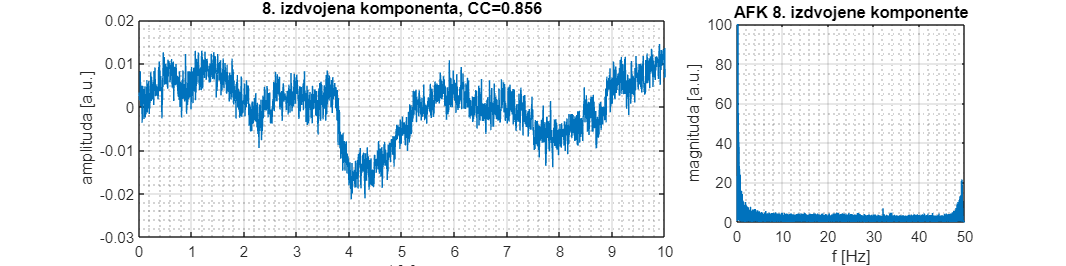

% Primena BSS-CCA u cilju izvajanja nezavisnih komponenti višekanalnog signala
[y_CCA,H_CCA,r] = ccabss_test_cc(EHG_data_filt');
y_CCA = real(y_CCA);

% Prikaz izdvojenih komponenti u vremenskom domenu i frekvencijskom
for i = 1:n_sig
    figure(position=[50 100 1000 250])
        subplot(1,3,[1 2])
        plot(t,y_CCA(i,:))
        xlabel('t [s]'); ylabel('amplituda [a.u.]')
        title(num2str(i) + ". izdvojena komponenta, CC=" + num2str(round(r(i),3)))
        grid on; grid minor
        xlim([0 10])
    
        data = y_CCA(i,:);
        data_fft = fftshift(fft(data));
        subplot(1,3,3)
        plot(f,abs(data_fft))
        xlabel('f [Hz]'); ylabel('magnituda [a.u.]')
        title("AFK " + num2str(i) + ". izdvojene komponente")
        grid on; grid minor
        xlim([0 50]);
        if i == 1
            ylim([0 1000])
        else 
            ylim([0 100])
        end
end

**Učitavanje dostupnih anotacija**

Kako bi se utvdilo da li je signal koji odgovara kontrakcijama materice uspešno izdvojen iz 3. izvorne konponente, isti će biti poređen sa dostupnim anotacijama. Za posmatrani signal dostupne su sledeće anotacije:

[ANN_C, ind_C, ANN_fm, ind_fm] = load_annotations(ANNFILE, fs, ind_start);

Pokret fetusa: 83.9 s
Kontrakcija: 144 s
Pokret fetusa: 253.8 s
Kontrakcija: 353.9 s
Kontrakcija: 548.8 s
Kontrakcija: 739.1 s
Kontrakcija: 893.8 s
Pokret fetusa: 1058.8 s
Kontrakcija: 1073.7 s
Kontrakcija: 1259.1 s
Kontrakcija: 1438.7 s


**Izdvajanje komponente koja odgovara mišićnoj aktivnosti materice**

Na sledećem grafiku ponovo je prikazan vremenski oblik 3. izvorne komponente, ali ovog puta na većoj vremenskoj skali, u celokupnom trajanju snimanja. Poređenjem sa dostupnim anotacijama koje odgovaraju kontrakcijama materice može se zaključiti da je u odgovarajućim vremenskim trenucima ove kontrakcije moguće prepoznati, ali da je signal jako zašumljen i da ga je potrebno ukloniti šum kako bi kontrakcije materice na njemu bile jasnije.

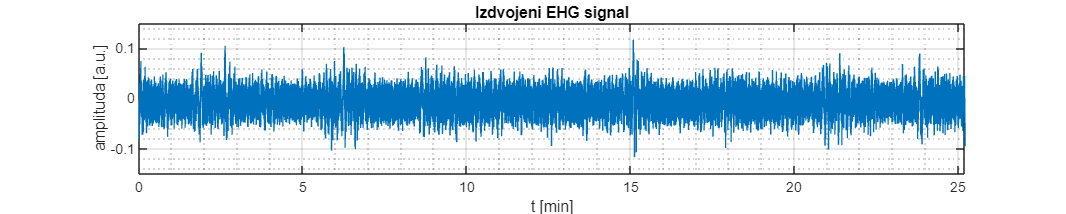

% Izdvajanje nezavisne komponente koja odgovara EHG signalu
EHG = y_CCA(3,:);

% Definisanje vremenske ose u minutima
t_min = t./60;

% Prikaz odabrane komponente
figure(position = [50,100,1000,200])
    plot(t_min,EHG)
    grid on; grid minor;
    xlabel('t [min]'); ylabel('amplituda [a.u.]');
    title('Izdvojeni EHG signal')
    xlim([0 t_min(end)])

**EMD ***(engl. Empirical Mode Decomposition)*

U literaturi je za odšumljivanje EHG signala nakon primene CCA algoritma korišćena EMD procedura **[1][2]**, te je ova procedura primenjena i ovde kako bi se iz EHG signala uklonili visokofrekventni artefakti.

Vremenski oblici IMF (*engl. Intrinsic Mode Function*) i reziduala dobijenih primenom EMD procedure prikazani su na graficima u nastavku.

Odšumljivaje EHG signala u vremenskom domenu izvršeno je rekonstrukcijom EHG signala iz njegovih IMF i reziduala, tako što su u procesu rekonstrukcije odbačene prve četiri IMF koje odgovaraju visokofrekventnim artefaktima. Vremenski oblici EHG signala pre i nakon ovakvog filtriranja prikazani su na sledećem grafiku.

[EHG_denoised] = EMD_denoising(EHG,fs);

% Prikaz originalnog i odšumljenog signala
figure(position=[50 100 1000 200])
    hold all
    plot(t,EHG)
    plot(t,EHG_denoised,'LineWidth',1.6)
    xlabel('t [s]'); ylabel('amplituda [a.u.]')
    title('Odšumljivanje EHG signala primenom EMD')
    grid on; grid minor
    xlim([0 10])

Na sledećem grafiku prikazana je uveličana amplitudska frekvencijska karakteristika filtriranog EHG signala, sa koje se može zaključiti da je EHG signal nakon filtriranja zadržao spektralne komponente u frekvencijskom opsegu 0.1-1.5 Hz koji odgovara opsegu frekvencija u kojima EHG signal po pravilu ima najvišu energiju.

% Prikaz AFK odšumljenog signala
figure(position = [50 100 1000 200])
    plot(f,abs(fftshift(fft(EHG_denoised))))
    xlabel('f [Hz]'); ylabel('magnituda [a.u.]')
    title('AFK odšumljenog EHG signala')
    grid on; grid minor
    xlim([0 3])

U nastavku je prikazan filtrirani EHG signal u svom celokupnom trajanju zajedno sa anotacijama koje odgovaraju kontrakcijama materice i ovim grafikom je potvrđeno da je filtriranje EHG-a uspešno urađeno jer se kontrakcije na EHG signalu sada lako mogu uočiti i golim okom. Bez obzira, u nastavku je sprovedeno i izdvajanje obvojnice filtriranog EHG signala kako bi se jasnije utvrdili počeci kontrakcija.

% Poređenje odšumljenog signala sa anotacijama koje odgovaraju kontrakcijama
figure(position=[50 100 1000 200])
    hold all
    plot(t_min,EHG_denoised)
    for i = 1:length(ANN_C)
        xline(ANN_C(i)/fs/60,'color','red','LineStyle','--','label','C','LabelOrientation','horizontal');
    end
    xlabel('t [min]'); ylabel('amplituda [a.u.]')
    title('EHG signal nakon odšumljivanja')
    grid on; grid minor
    xlim([t_min(1) t_min(end)])

**Izdvajanje anvelope filtriranog EHG signala**

Izdvajanje obvojnice filtriranog EHG signala sprovedeno je tako što je signal najpre dvostrano ispravljen kvadriranjem, a potom je izvršena integracija signala primenom *zero-phase* MA (*engl. Moving Average*) filtriranja i dobijena anvelopa normalizovana je svojom maksimalnom vrednošću. Maksimalna vrednost koja će biti korišćena prilikom normalizacije nije tražena u poslednjih N*fs odbiraka anvelope EHG signala (N je red MA filtra, a fs frekvencija odabiranja signala), jer u ovom delu dolazi do distorzije signala zbog nedostka odbiraka za MA filtriranje. U nastavku su prikazani koraci u izdvajanju anvelope i dobijeni rezultati za slučaj dva različita reda MA filtra.

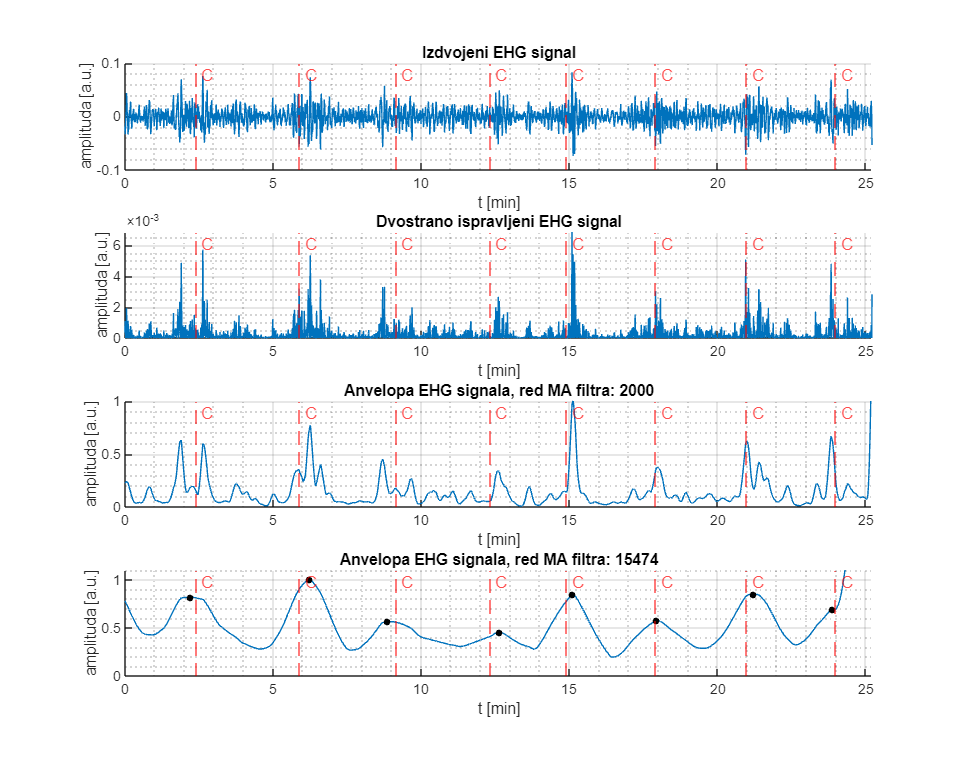

[EHG_envelope_norm, EHG_envelope_norm2] = envelope_extraction(EHG_denoised,ANN_C)

% Nalaženje lokalnih maksimuma izdvojene anvelope
[peaks,locs] = findpeaks(EHG_envelope_norm2,'MinPeakDistance',10*fs);

% Poređenje rezultata sa anotacijama koje odgovaraju kontrakcijama
figure(position=[50 100 1000 800])
    subplot(4,1,1)
    hold all
    plot(t_min,EHG_denoised)
    for i = 1:length(ANN_C)
        xline(ANN_C(i)/fs/60,'color','red','LineStyle','--','label','C','LabelOrientation','horizontal');
    end
    xlabel('t [min]'); ylabel('amplituda [a.u.]')
    title('Izdvojeni EHG signal')
    grid on; grid minor
    xlim([t_min(1) t_min(end)])

    subplot(4,1,2)
    hold all
    plot(t_min,EHG_sq)
    for i = 1:length(ANN_C)
        xline(ANN_C(i)/fs/60,'color','red','LineStyle','--','label','C','LabelOrientation','horizontal');
    end
    xlabel('t [min]'); ylabel('amplituda [a.u.]')
    title('Dvostrano ispravljeni EHG signal')
    grid on; grid minor
    xlim([t_min(1) t_min(end)])

    subplot(4,1,3)
    hold all
    plot(t_min,EHG_envelope_norm)
    for i = 1:length(ANN_C)
        xline(ANN_C(i)/fs/60,'color','red','LineStyle','--','label','C','LabelOrientation','horizontal');
    end
    xlabel('t [min]'); ylabel('amplituda [a.u.]')
    title("Anvelopa EHG signala, red MA filtra: " + num2str(order))
    grid on; grid minor
    xlim([t_min(1) t_min(end)]); ylim([0 1])

    subplot(4,1,4)
    hold all
    plot(t_min,EHG_envelope_norm2)
    for i = 1:length(ANN_C)
        xline(ANN_C(i)/fs/60,'color','red','LineStyle','--','label','C','LabelOrientation','horizontal');
    end
    scatter(t_min(locs),peaks,'filled','sizeData',12,...
        'MarkerEdgeColor','black','MarkerFaceColor','black')
    xlabel('t [min]'); ylabel('amplituda [a.u.]')
    title("Anvelopa EHG signala, red MA filtra: " + num2str(order2))
    grid on; grid minor
    xlim([t_min(1) t_min(end)]); ylim([0 1.1])

U prvom slučaju je red MA filtra 2000 i filtriranjem ovakvim filtrom obezbeđeno je da anvelopa signala dobro prati promene u dinamici kontrakcija. U drugom slučaju, red MA filtra određen je kao polovina minimalnog broja odbiraka između dve susedne kontrakcije dostupnih u anotacijama. Na ovako izdvojenoj anvelopi detektovani su lokalni maksimumi (tačke označene crnom bojom na poslednjem grafiku), koji se u slučaju svih kontrakcija nalaze u neposrednoj blizini anotacija koje odgovaraju kontrakcijama. Zanimljivo je primetiti da se oblik ovako izdvojene anvelope u velikoj meri podudara sa oblikom signala sa takograma, što dodatno potvrđuje da je za izdvajanje EHG signala nakon primene CCA algoritma odabrana dobra izvorna komponenta.

**Detekcija R pikova na izdvojenoj komponenti koja odgovara EKG signalu trudnice**

Još jedna tačka zadatka jeste određivanje RR intervala na prvoj izdvojenoj komponenti (onoj komponenti koja odgovara EKG signalu majke). Vremenski oblik ove izvorne komponente još jednom je prikazak u nastavku.

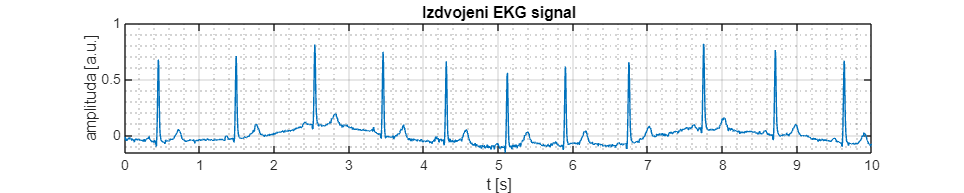

% Izdvajanje komponente koja odgovara EKG signalu
ECG = y_CCA(1,:);

% Prikaz izdvojene komponente u vremenskom domenu
figure(position = [50,100,1000,200])
    plot(t,ECG)
    grid on; grid minor;
    xlabel('t [s]'); ylabel('amplituda [a.u.]');
    title('Izdvojeni EKG signal')
    xlim([0 10])

Za izdvajanje R pikova na ovom signalu primenjen je modifikovan Pan-Tompkins algoritam (razlika u odnosu na originalni Pan-Tompkins algoritam jeste u tome što originalni algoritam koristi 2 praga za detekciju R pikova, a ovde je korišćen samo jedan). Koraci koji su izvršeni prilikom izdvajanja R pikova su sledeći:

- *lowpass* filtriranje signala filtrom drugog reda čija je frekvencija odsecanja oko 11 Hz i koji unosi kašnjenje od 5 odbiraka prilikom filtriranja *filter()* funkcijom;

- normalizacija signala njegovom maksimalnom vrednošću, pri čemu je parametar *alpha* koji određuje početni odbirak od koga će se tražiti maksimalna vrednost signala postavljen na vrednost 0.5;

- *highpass* filtriranje signala filtrom čija je frekvencija odsecanja oko 5 Hz i koji unosi kašnjenje od 16 odbiraka prilikom filtriranja *filter()* funkcijom;

- diferencijacija signala koja unosi kašnjenje od 2 odbirka;

- kvadriranje signala;

- *zero-phase* filtriranje signala MA filtrom reda 10, primenom *filtfilt()* funkcije;

- detekcija R pikova jednostavnim poređenjem sa pragom, pri čemu prag ima vrednost od 35 % maksimalne vrednosti signala dobijenog integracijom, a *blanking* period iznosi 40 odbiraka;

- kompenzacija kašnjenja od 5+16+2 = 23 odbirka koje je nastalo kao posledica primene prvog, trećeg i četvrtog koraka.

Amplitudska frekvencijska karakteristika *bandpass* filtra koji predstavlja kaskadnu vezu *lowpass* i *highpass* filtra, međukoraci u izdvajanju *feature* signala na kome se detektuju R pikovi, kao i rezultati detekcije R pikova prikazani su na sledećim graficima.

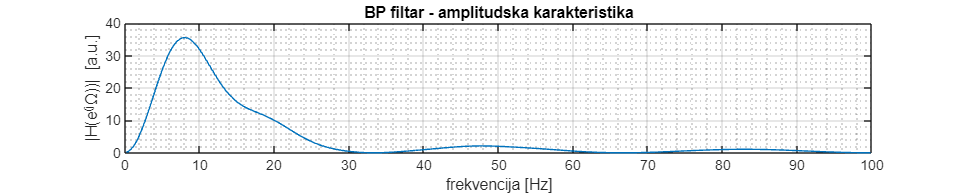

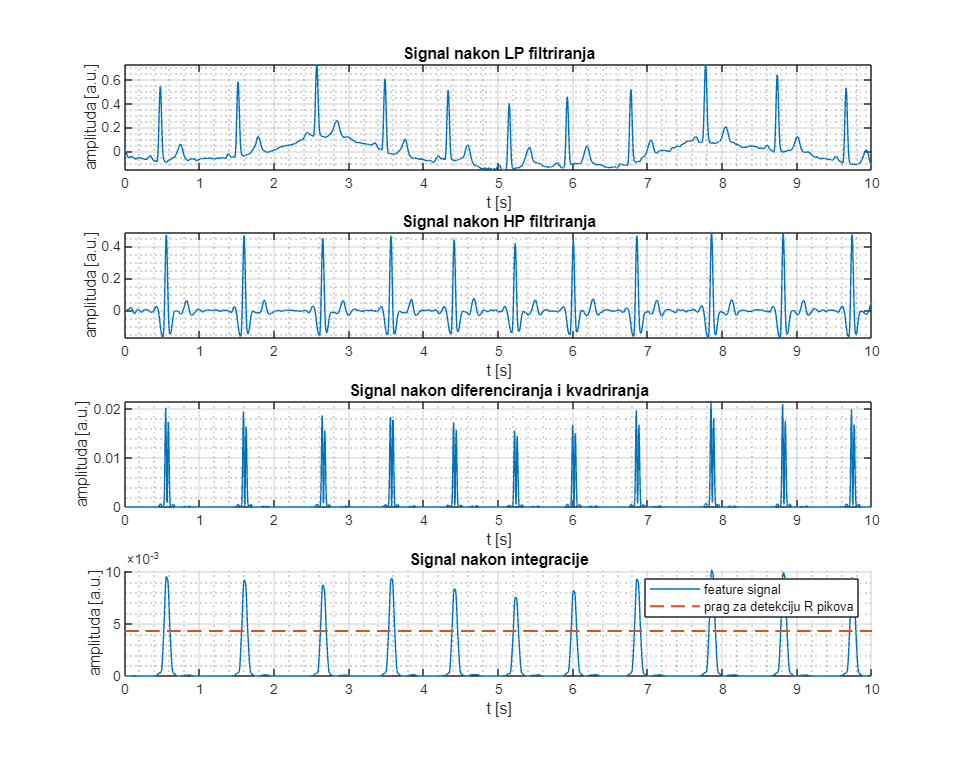

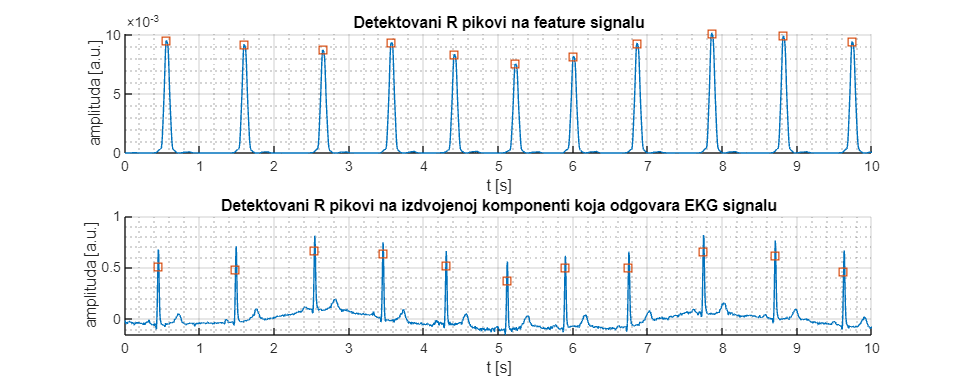

% Parametri Pan-Tompkins algoritma
alpha = 0.5; % 0.5-0.9
N = 10;
fraction = 0.35; % 0.3-0.4

% Detekcija R pikova primenom Pan-Tompkins algoritma
beat = Pan_Tompkin_QRS(ECG, fs, alpha, N, fraction);

Na ovaj način detektovano je ukupno 1844 R pikova i na osnovu njih izračunata su trajanja odgovarajućih RR intervala. Promene trajanja RR intervala tokom vremena prikazane su na sledećim graficima.

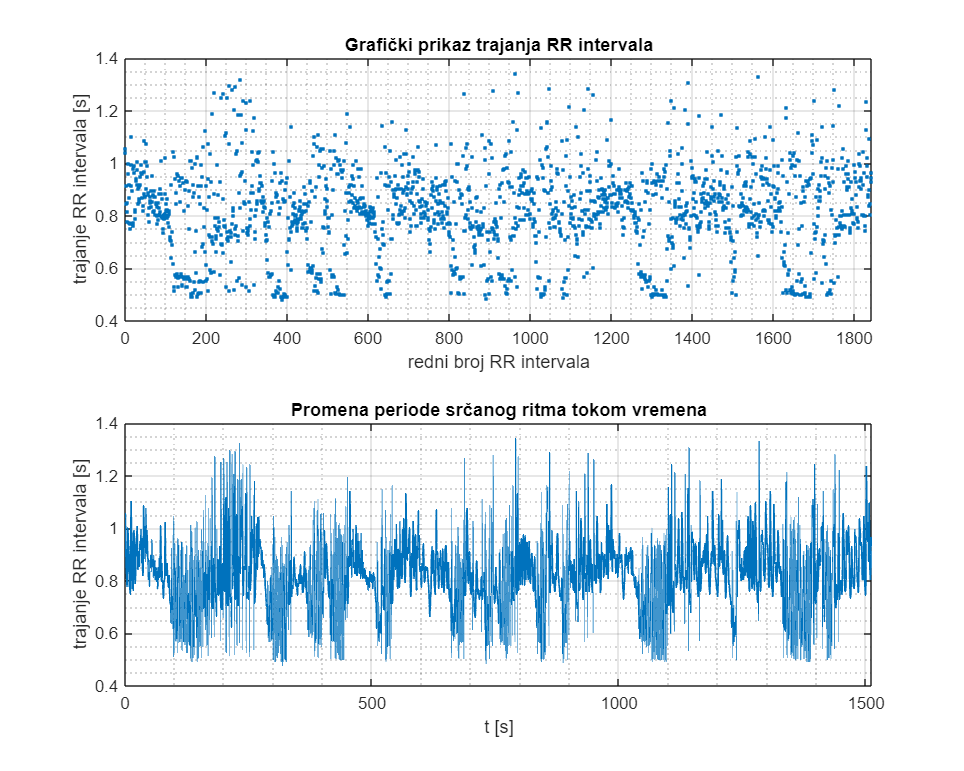

% Računanje trajanja RR intervala na osnovu detektovanih pikova
n_beats = length(beat);
RR = zeros(1,n_beats-1);

for i = 1:(n_beats-1)
    RR(i) = (beat(i+1)-beat(i))/fs; % s
end
RR_timestaps = linspace(0,t(end),length(RR));

% Grafički prikaz trajanja RR intervala
figure(position=[50 100 1000 800])
    subplot(2,1,1)
    plot(RR,'.','LineWidth',1)
    xlabel('redni broj RR intervala'); ylabel('trajanje RR intervala [s]')
    title('Grafički prikaz trajanja RR intervala')
    grid on; grid minor
    xlim([0 length(RR)])
    subplot(2,1,2)
    plot(RR_timestaps,RR,'LineWidth',1)
    xlabel('t [s]'); ylabel('trajanje RR intervala [s]')
    title('Promena periode srčanog ritma tokom vremena')
    grid on; grid minor
    xlim([RR_timestaps(1) RR_timestaps(end)])

Sa prikazanih grafika, kao i sa histograma trajanja RR intervala koji je prikazan u nastavku, možemo zaključiti da trajanje RR intervala nije ni približno konstantno tokom vremena tj. da izdvojeni EKG signal nije stacionaran. Medijana trajanja RR intervala je 0.825 s, a medijana pulsa je 72.727 bpm (*engl. beats-per-minute*).

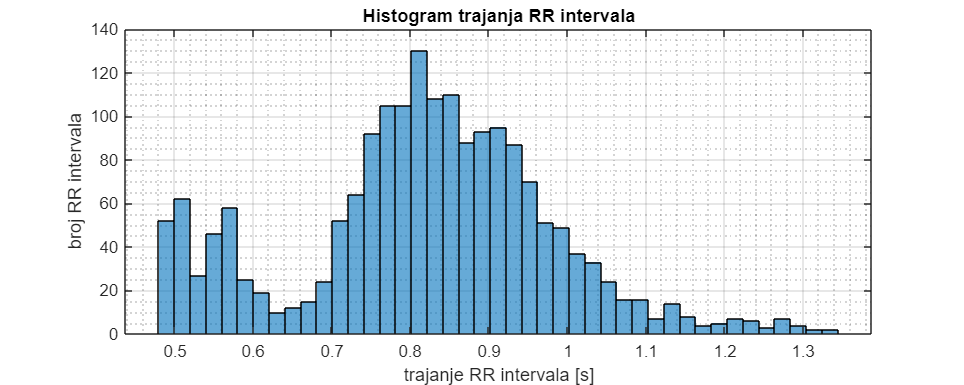

% Prikaz histograma trajanja RR intervala
figure(position=[50 100 1000 400])
    histogram(RR,round(sqrt(length(RR))))
    xlabel('trajanje RR intervala [s]'); ylabel('broj RR intervala')
    title('Histogram trajanja RR intervala')
    grid on; grid minor

% Računanje brzine srčanog ritma
HR = 60./RR;    % heart rate [bpm]
    
% Računanje medijane trajanja RR intervala i medijane HR
RR_median = median(RR);
HR_median = median(HR);
disp("Medijana RR: " + num2str(round(RR_median,3)) + " s" + newline + ...
    "Medijana HR: " + num2str(round(HR_median,3)) + " bpm")

Medijana RR: 0.825 s
Medijana HR: 72.727 bpm


Na sledećem grafiku prikazana je raspodela trajanja RR intervala pomoću *boxplot*-a. Crna tačka na prikazanom grafiku odgovara medijani trajanja RR intervala, dok plavi trouglasti "zupci" oko nje predstavljaju intervale poverenja od 95 % za medijanu. Leva i desna vertikalna plava linija predstavljaju prvi kvartil Q1 (25. percentil) i treći kvartil Q3 (75. percentil), tj. vrednosti ispod kojih se nalazi 25 % tj. 75 % vrednosti trajanja RR intervala. Crne isprekidane linije pružaju se duž svih onih vrednosti trajanja RR intervala koje se ne smatraju *outlier*-ima, dok crveni krstići predstavljaju *outlier*-e trajanja RR intervala (ovakvih vrednosti ima 31).

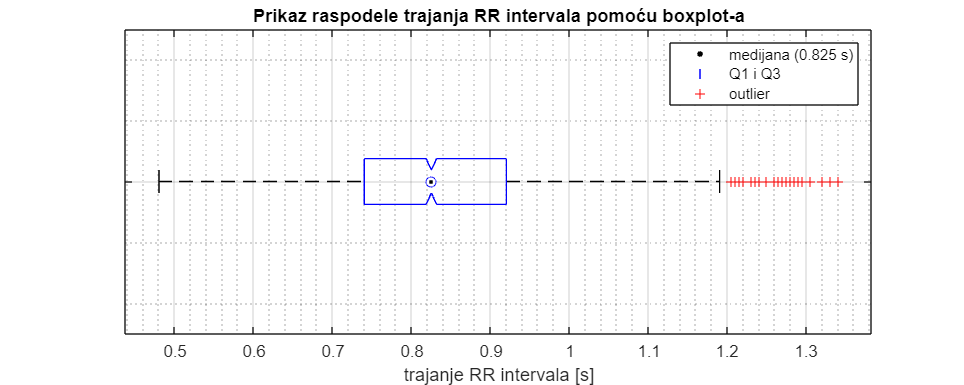

% Prikaz raspodele trajanja RR intervala pomoću boxplot-a
figure(position=[50 100 1000 400])
    boxplot(RR,'notch','on','Orientation','horizontal','MedianStyle','target')
    hold all
    plot(NaN,NaN,'k.', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', "medijana ("+num2str(RR_median)+" s)")
    plot(NaN,NaN,'b|', 'LineWidth', 1, 'DisplayName', 'Q1 i Q3')
    plot(NaN,NaN,'r+', 'DisplayName', 'outlier')
    legend('show','Location','northeast')
    title('Prikaz raspodele trajanja RR intervala pomoću boxplot-a')
    grid on; grid minor
    xlabel('trajanje RR intervala [s]')
    yticklabels([])

**Provera periodičnosti srčanog ritma**

Na osnovu ranije prikazanih grafika promene trajanja RR intervala tokom vremena, jasno je da srčani ritam u ovom slučaju nije deterministički već stohastički i to visokog varijabiliteta. Ovo se može potvrditi i posmatranjem normalizovane autokorelacione funkcije EKG signala, koja je prikazana u nastavku. Za determinističke signale, vrednost normalizovane autokorelacione funkcije ima vrednost 1 za onu vrednost pomeraja (*engl. lag*) koja odgovara periodi signala, što ovde nije slučaj jer normalizovana autokorelaciona funkcija ima vrednost 1 samo za pomeraj koji je jednak 0 (sličnost signala sa samim sobom).

Za stohastičke signale sa periodičnošću jedan od načina da se proceni osnovna učestanost signala jeste da se odredi *lag* za koji autokorelaciona funkcija ima globalni maksimum (ignoriše se globalni maksimum za *lag* jednak 0). U konkretnom slučaju, taj maksimum bi se dobio za vrednost *lag*-a 54, što bi odgovaralo osnovnoj učestanosti od 3.774 Hz. Ovaj rezltat nema smisla, jer bi on odgovarao trajanju RR intervala od 0.265 s, a takav RR interval ne postoji među detektovanim RR intervalima.

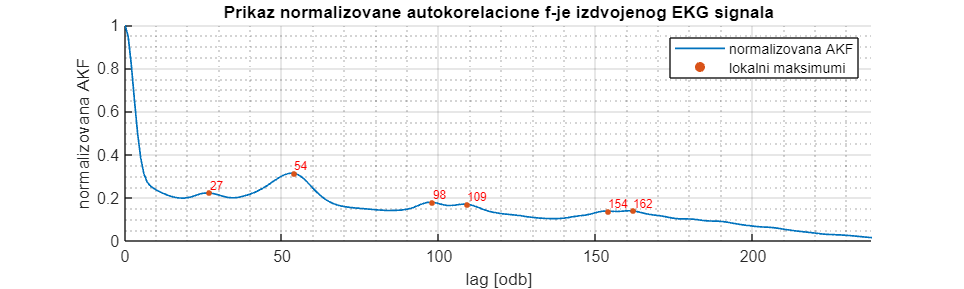

% Računanje normalizovane autokorelacione funkcije izdvojenog EKG signala
MAXLAG = fs*1.19;
[rho, lags] = xcorr(ECG,MAXLAG,'normalized');

% Izdvajanje jednostrane normalizovane autokorelacione f-je
lags = lags((length(rho)+1)/2:end);
rho = rho((length(rho)+1)/2:end);

% Nalaženje lokalnih maksimuma normalizovane autokorelacione f-je
[peaks, locs] = findpeaks(rho);

% Prikaz normalizovane autokorelacione f-je i detektovanih lokalnih maksimuma
figure(position=[50 100 1000 300])
    hold all
    plot(lags,rho,'LineWidth',1)
    scatter(locs,peaks,'filled','SizeData',12)
    xlabel('lag [odb]'); ylabel('normalizovana AKF')
    title('Prikaz normalizovane autokorelacione f-je izdvojenog EKG signala')
    legend('normalizovana AKF','lokalni maksimumi')
    for i = 1:length(locs)
        text(locs(i),peaks(i),num2str(locs(i)),'Color','red','FontSize',7,...
             'VerticalAlignment','bottom','HorizontalAlignment','left');
    end
    grid on; grid minor
    xlim([0 MAXLAG])

% Određivanje osnovnih učestanosti koje odgovaraju lokalnim maksimumima
frequencies = fs./lags(locs);
disp("Lokalni maksimumi odgovaraju sledećim učestanostima u Hz: " + newline + num2str(round(frequencies,3)))

Lokalni maksimumi odgovaraju sledećim učestanostima u Hz: 
7.692       3.774       2.062       1.852       1.307       1.242


Prilikom traženja lokalnih maksimuma autokorelacione funkcije u cilju određivanja osnovne učestanosti srčanog ritma, treba razmatrati samo opseg *lag*-ova koji bi rezultovao periodom RR intervala koja je smislena i nalazi se u opsegu detektovanih RR intervala, što je u konkretnom slučaju opseg *lag*-ova [96, 238]. Oblik normalizovane autokorelacione funkcije za ovaj opseg *lag*-ova ponovo je prikazan u nastavku. Normalizovana autokorelaciona funkcija na ovom intervalu ima maksimum za vrednost* lag*-a 161, što odgovara osnovnoj učestanosti 1.242 Hz tj. trajanju RR intervala od 0.805 s, što je sasvim smislen rezultat s obzirom na to da je medijana trajanja RR intervala 0.825 s.

% Definisanje opsega od interesa za određivanje periode srčanog ritma
MINLAG = fs*min(RR);

disp("Lokalni maksimum AKF koji odgovara osnovnoj učestanosti srčanog ritma " + ...
    "traži se u opsegu lag-ova: [" + num2str(MINLAG) + ", " + num2str(MAXLAG) + "]")

Lokalni maksimum AKF koji odgovara osnovnoj učestanosti srčanog ritma traži se u opsegu lag-ova: [96, 238]


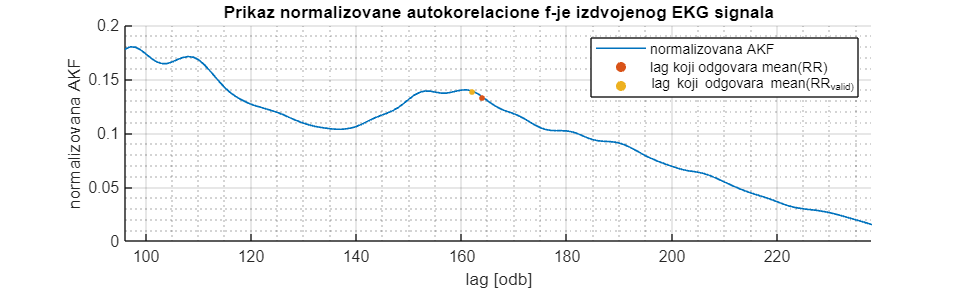

% Prikaz normalizovane AKF u opsegu lagova od interesa

RR_mean = mean(RR);
lag_RR_mean = round(fs*RR_mean);

RR_wo = RR(RR <= 1.19); % RR intervali bez outlier-a
RR_mean_wo = mean(RR_wo);
lag_RR_mean_wo = round(fs*RR_mean_wo);

figure(position=[50 100 1000 300])
    hold all
    plot(lags,rho,'LineWidth',1)
    scatter(lag_RR_mean,rho(lags==lag_RR_mean),'filled','SizeData',12);
    scatter(lag_RR_mean_wo,rho(lags==lag_RR_mean_wo),'filled','SizeData',12);
    xlabel('lag [odb]'); ylabel('normalizovana AKF')
    title('Prikaz normalizovane autokorelacione f-je izdvojenog EKG signala')
    legend('normalizovana AKF','lag koji odgovara mean(RR)',...
        'lag koji odgovara mean(RR_valid)')
    grid on; grid minor
    xlim([MINLAG MAXLAG])

% Procena osnovne učestanosti srčanog ritma
fundamental_frequency = fs/161;
disp("Procenjenja osnovna učestanost signala: " + num2str(round(fundamental_frequency,3)) + " Hz" ...
    + newline + "Procenjenja osnovna perioda signala: " + num2str(round(1/fundamental_frequency,3)) + " s")

Procenjenja osnovna učestanost signala: 1.242 Hz
Procenjenja osnovna perioda signala: 0.805 s


**Poincaré-ov grafik**

Određivati osnovnu učestanost srčanog ritma ima smisla u slučaju stabilnog srčanog ritma. Međutim, ukoliko je srčani ritam nestacionaran, nelinearan ili čak haotičan, postavlja se pitanje koji je tačno smisao određene osnovne učestanosti srčanog ritma.

Jedan od načina da se analizira varijabilnost srčanog ritma (*engl. Heart Rate Variability* - HRV) jeste prikazivanjem *Poincaré*-ovog grafika koji predstavlja zavisnost trajanja RR intervala od trajanja narednog RR intervala. Sa ovog grafika se vizuelnom inspekcijom oblika grafika ili kvalitativno nalaženjem karakterističnih parametara SD1 (standardna devijacija trenutne varijabilnosti RR intervala) i SD2 (standardna devijacija dugoročne varijabilnosti RR intervala) ili njihovog odnosa SD1/SD2 može analizirati varijabilnost srčanog ritma.

U nastavku je prikazan *Poincaré*-ov grafik svih detektovanih RR intervala, kao i vrednosti karakterističnih parametara SD1, SD2, SD1/SD2.

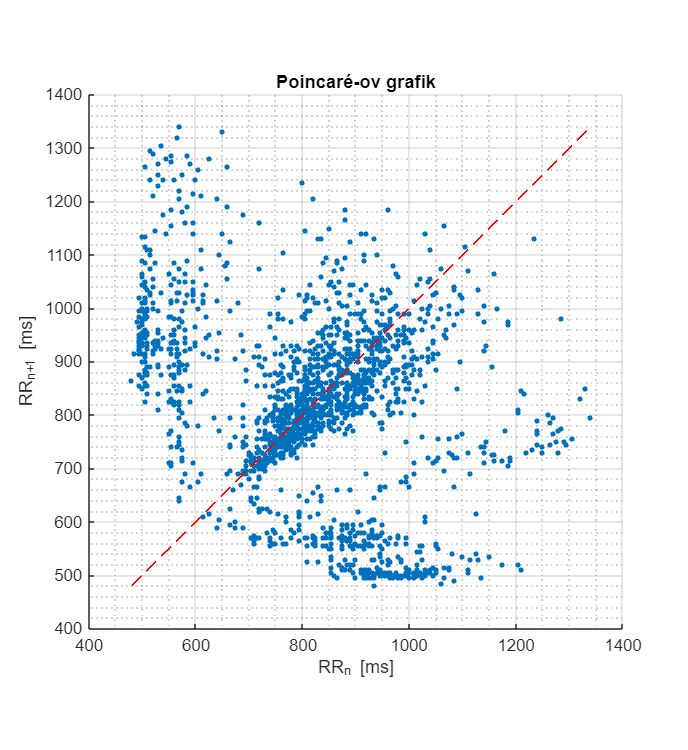

% Prikaz Poincaré-ovog grafika detektovanih RR intervala

RR_i = RR(1:end-1);
RR_i_plus_1 = RR(2:end);

x = linspace(min(RR_i),max(RR_i),length(RR_i));

figure(position=[50 100 550 600])
    hold all
    scatter(1e3*RR_i,1e3*RR_i_plus_1,'filled','SizeData',10)
    plot(1e3*x,1e3*x,'r--','LineWidth',1)
    xlabel('RR_n [ms]'); ylabel('RR_n_+_1 [ms]')
    title('Poincaré-ov grafik')
    grid on; grid minor
    axis equal
    xlim([400 1400]); ylim([400 1400])

% Parametri SD1 i SD2 Poincaré-ovog grafika
SD1 = std(RR_i_plus_1 - RR_i)/sqrt(2);
RR_mean = mean(RR);
SD2 = std(RR_i_plus_1 + RR_i - 2*RR_mean)/sqrt(2);

disp("SD1: " + num2str(SD1) + newline + "SD2: " + num2str(SD2) + newline + "SD1/SD2: "  + num2str(SD1/SD2));

SD1: 0.18597
SD2: 0.1354
SD1/SD2: 1.3735


Zanimljivo je prikazati kako promene u vremenskom obliku EKG signala utiču na promene u izgledu *Poincaré*-ovog grafika. Zbog toga su izdvojena dva karakteristična segmenta iz EKG signala (EKG signal je nestacionaran) - jedan u kome su svi R pikovi na približno istom odstojanju (susedni RR intervali su približno istog trajanja) i jedan u kome se RR intervali kraćeg i dužeg trajanja naizmenično smenjuju. Za oba slučaja prikazani su odgovarajući *Poincaré*-ovi grafici. Činjenica da su u prvom slučaju susedni RR intervali približno istog trajanja na *Poincaré*-ovom grafiku ogleda se u tome da su tačke koncetrisane duž prave x=y, dok u drugom slučaju *Poincaré*-ov grafik ima oblik normale na pravu x=y.

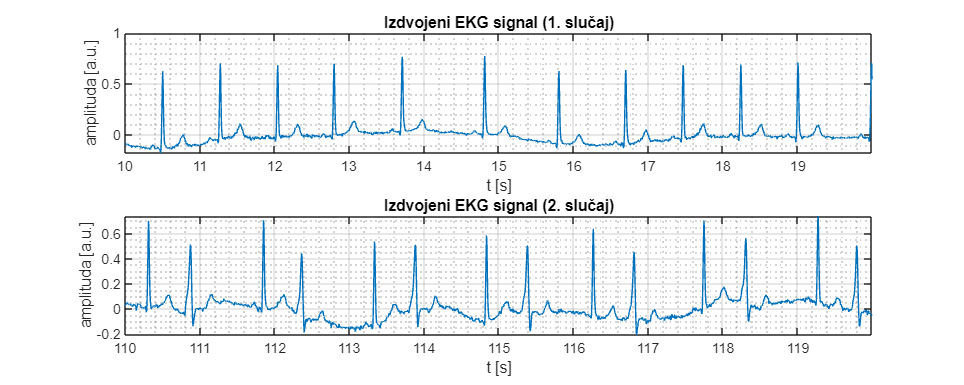

% Prikaz Poincaré-ovih grafika za različite vremenske intervale EKG signala

ind_start1 = 10*fs;
ind_end1 = 60*fs;
t_tmp1 = t(ind_start1:ind_end1);

ind_start2 = 110*fs;
ind_end2 = 160*fs;
t_tmp2 = t(ind_start2:ind_end2);

figure(position=[50 100 1000 400])
orient landscape
    subplot(2,1,1)
    plot(t_tmp1,ECG(ind_start1:ind_end1))
    grid on; grid minor
    title("Izdvojeni EKG signal (1. slučaj)")
    xlabel('t [s]'); ylabel('amplituda [a.u.]')
    xlim([t_tmp1(1) t_tmp1(1)+10])

    subplot(2,1,2)
    plot(t_tmp2,ECG(ind_start2:ind_end2))
    grid on; grid minor
    title("Izdvojeni EKG signal (2. slučaj)")
    xlabel('t [s]'); ylabel('amplituda [a.u.]')
    xlim([t_tmp2(1) t_tmp2(1)+10])

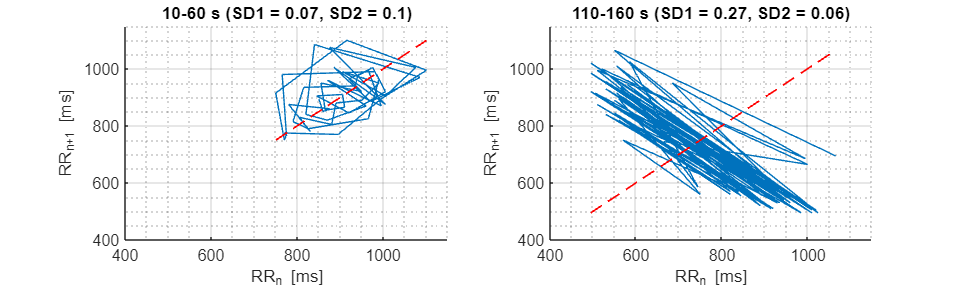

figure(position=[50 100 1000 300])
    subplot(1,2,1)
    beat_tmp = Pan_Tompkin_QRS(ECG(ind_start1:ind_end1), fs, alpha, N, fraction, false);
    RR_tmp = zeros(1,length(beat_tmp)-1);
    for i = 1:(length(beat_tmp)-1)
        RR_tmp(i) = (beat_tmp(i+1)-beat_tmp(i))/fs; % s
    end
    RR_tmp_i = RR_tmp(1:end-1);
    RR_tmp_i_plus_1 = RR_tmp(2:end);
    x_tmp = linspace(min(RR_tmp),max(RR_tmp),length(RR_tmp_i));
    
    SD1_tmp = std(RR_tmp_i_plus_1 - RR_tmp_i)/sqrt(2);
    RR_tmp_mean = mean(RR_tmp);
    SD2_tmp = std(RR_tmp_i_plus_1 + RR_tmp_i - 2*RR_tmp_mean)/sqrt(2);

    hold all
    plot(1e3*RR_tmp_i,1e3*RR_tmp_i_plus_1,'LineWidth',0.6)
    plot(1e3*x_tmp,1e3*x_tmp,'r--','LineWidth',1)
    xlabel('RR_n [ms]'); ylabel('RR_n_+_1 [ms]')
    title(num2str(round(t_tmp1(1),1)) + "-" + num2str(round(t_tmp1(end),1)) + " s" + ...
        " (SD1 = " + num2str(round(SD1_tmp,2)) + ", SD2 = " + num2str(round(SD2_tmp,2))+ ")")
    grid on; grid minor
    xlim([400 1150]); ylim([400 1150]);

    subplot(1,2,2)
    beat_tmp = Pan_Tompkin_QRS(ECG(ind_start2:ind_end2), fs, alpha, N, fraction, false);
    RR_tmp = zeros(1,length(beat_tmp)-1);
    for i = 1:(length(beat_tmp)-1)
        RR_tmp(i) = (beat_tmp(i+1)-beat_tmp(i))/fs; % s
    end
    RR_tmp_i = RR_tmp(1:end-1);
    RR_tmp_i_plus_1 = RR_tmp(2:end);
    x_tmp = linspace(min(RR_tmp),max(RR_tmp),length(RR_tmp_i));

    SD1_tmp = std(RR_tmp_i_plus_1 - RR_tmp_i)/sqrt(2);
    RR_tmp_mean = mean(RR_tmp);
    SD2_tmp = std(RR_tmp_i_plus_1 + RR_tmp_i - 2*RR_tmp_mean)/sqrt(2);

    hold all
    plot(1e3*RR_tmp_i,1e3*RR_tmp_i_plus_1,'LineWidth',0.6)
    plot(1e3*x_tmp,1e3*x_tmp,'r--','LineWidth',1)
    xlabel('RR_n [ms]'); ylabel('RR_n_+_1 [ms]')
    title(num2str(round(t_tmp2(1),1)) + "-" + num2str(round(t_tmp2(end),1)) + " s" + ...
        " (SD1 = " + num2str(round(SD1_tmp,2)) + ", SD2 = " + num2str(round(SD2_tmp,2))+ ")")
    grid on; grid minor    
    xlim([400 1150]); ylim([400 1150]);

**Reference**

**[1] **Hassan, M., Boudaoud, S., Terrien, J., Karlsson, B., & Marque, C. (2011). Combination of canonical correlation analysis and empirical mode decomposition applied to denoising the labor electrohysterogram. *IEEE transactions on bio-medical engineering*, *58*(9), 2441–2447. [https://doi.org/10.1109/TBME.2011.2151861](https://doi.org/10.1109/TBME.2011.2151861)

**[2]** Taralunga, D. D., Ungureanu, M., Hurezeanu, B., Gussi, I., & Strungaru, R. (2015). Empirical mode decomposition applied for non-invasive electrohysterograhic signals denoising. *Annual International Conference of the IEEE Engineering in Medicine and Biology Society. IEEE Engineering in Medicine and Biology Society. Annual International Conference*, *2015*, 4134–4137. [https://doi.org/10.1109/EMBC.2015.7319304](https://doi.org/10.1109/EMBC.2015.7319304)